# SSB资源映射

SSB（Synchronization Signal Block）信道是一种用于同步和小区搜索的重要信道。

SSB信道在NR系统中有着重要的作用，它主要用于以下几个方面：

- **小区检测和搜索**： 移动设备在建立连接之前需要找到可用的小区。SSB信道的作用之一就是帮助移动设备检测和搜索附近的小区。移动设备可以依靠SSB信道的存在来确认是否有可用的小区，并进一步获取小区的系统信息。

- **定时和同步**： SSB信道还用于定时和同步移动设备与基站之间的通信。移动设备通过解码SSB中的信息，可以获取基站的系统帧号（SFN）和子帧号（Subframe Number），从而实现在时间上与基站的同步。

- **切换和测量**： 移动设备在移动过程中需要进行小区之间的切换和测量，以保持最佳的连接质量。SSB信道的信息可以用来辅助移动设备进行切换决策和测量报告，以提供更好的用户体验。

- **初始接入**： 新的移动设备需要与小区建立初始连接，这涉及到随机接入过程。在初始接入过程中，移动设备通过监听SSB信道来感知小区的存在，然后根据一定的规则选择一个合适的预设的信道资源进行随机接入。

SSB包括PSS、SSS、PBCH和PBCH DMRS，在时域包含4个OFDM符号，在频域上包含240个连续子载波，SSB的时频结构如下图所示。

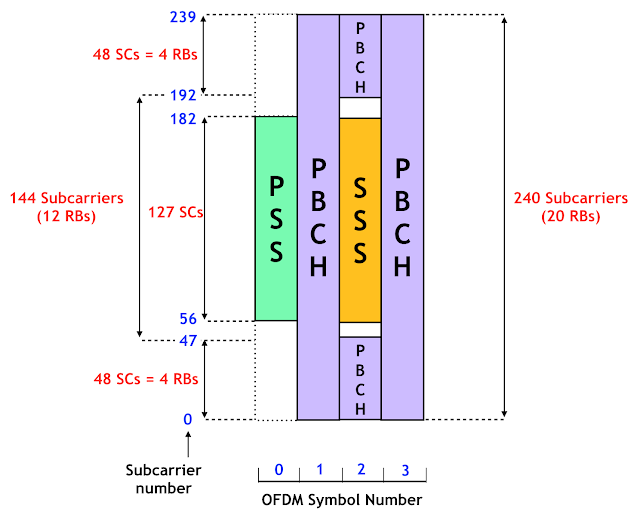

## 1 载波配置

clear;
clc;
close all;

% Carrier configuration
carrier = nrCarrierConfig;
carrier.NCellID = 2;                    % Cell identity
carrier.SubcarrierSpacing = 30;         % Carrier/BWP Subcarrier spacing
carrier.CyclicPrefix = 'normal';        % Cyclic prefix
carrier.NSlot      = 0;                 % Slot counter
carrier.NFrame     = 0;                 % Frame counter
carrier.NStartGrid = 0;                 % Carrier offset
carrier.NSizeGrid  = 51;                % Size of carrier in RB

## 2 MIB消息

MIB消息payload总计24bit，各字段bit数位域和长度如下所示。

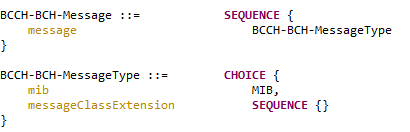

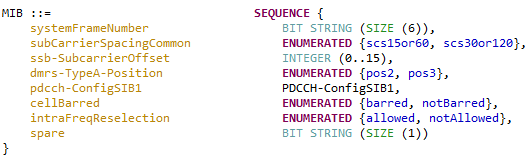

% MIB
MIB.systemFrameNumber = carrier.NFrame;            % 6bit
MIB.subCarrierSpacingCommon = 30;                  % 1bit 15\30\60\120
MIB.ssbSubcarrierOffset = 0;                       % 4bit 0-15
MIB.dmrsTypeAPosition = 2;                         % 1bit 2/3 
MIB.pdcchConfigSIB1.controlResourceSetZero = 10;   % 4bit 38213-13 table 0-15
MIB.pdcchConfigSIB1.searchSpaceZero = 4;           % 4bit 38213-13 table 0-15
MIB.cellBarred = 1;                                % 1bit 0:barred, 1:notBarred
MIB.intraFreqReselection = 0;                      % 1bit 0:allowed, 1:notAllowed
MIB.spare = 0;                                     % 1bit
disp(MIB)

          systemFrameNumber: 0
    subCarrierSpacingCommon: 30
        ssbSubcarrierOffset: 0
          dmrsTypeAPosition: 2
            pdcchConfigSIB1: [1×1 struct]
                 cellBarred: 1
       intraFreqReselection: 0
                      spare: 0



% Generate MIB payload
mibpayload = zeros(24,1);                          % 1bit BCCH-BCH-MessageType indication
SFN = dec2bin(fix(MIB.systemFrameNumber),10)=='1';
mibpayload(2:7) = SFN(1:6);
mibpayload(8) = (MIB.subCarrierSpacingCommon == 30)||(MIB.subCarrierSpacingCommon == 120);
mibpayload(9:12) = dec2bin(MIB.ssbSubcarrierOffset,4)=='1';
mibpayload(13) = (MIB.dmrsTypeAPosition == 3);
mibpayload(14:17) = dec2bin(MIB.pdcchConfigSIB1.controlResourceSetZero,4)=='1';
mibpayload(18:21) = dec2bin(MIB.pdcchConfigSIB1.searchSpaceZero,4)=='1';
mibpayload(22) = MIB.cellBarred;
mibpayload(23) = MIB.intraFreqReselection;
mibpayload(24) = MIB.spare;
disp(mat2str(mibpayload))

[0;0;0;0;0;0;0;1;0;0;0;0;0;1;0;1;0;0;1;0;0;1;0;0]


## 3 SSB配置

主要配置SSB的周期、半帧位置、模式、波束个数、频域位置等。

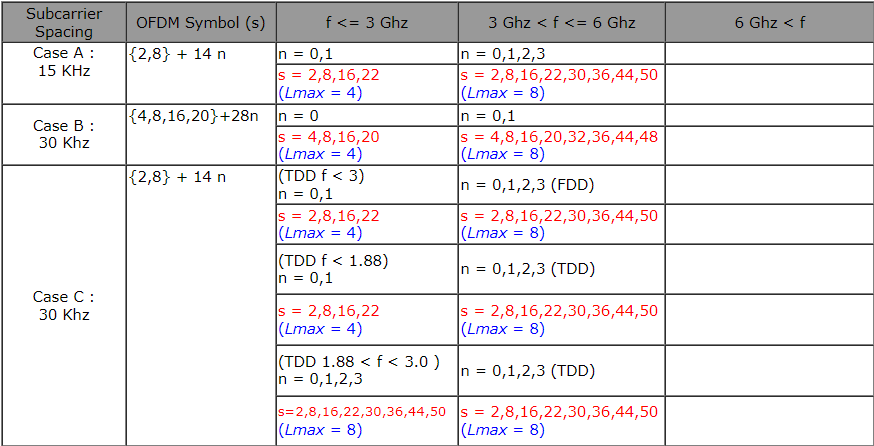

burst.BlockPattern = 'Case C';                  % Case A/B/C/D/E   Cases A/B/C for FR1, cases D/E for FR2.
burst.NFrame = 0;                               % System Frame Number (0...1023) (default 0)
burst.NHalfFrame = 0;                           % 0:前半帧  1:后半帧
burst.TransmittedBlocks = [0 1 0 1 0 1 0 1];    % L =4/8/64
burst.Period = 20;                              % Burst set periodicity in ms, (5, 10, 20, 40, 80, 160)
burst.k_SSB = 0;
burst.k0_offset = 0;

info = ssBurstInfo(burst);
disp(info)

                      L: 8
               SSBIndex: [1 3 5 7]
                  i_SSB: [1 3 5 7]
               ibar_SSB: [1 3 5 7]
        OccupiedSymbols: [4×4 double]
                  k_SSB: 0
    OccupiedSubcarriers: [240×1 double]



## 4 资源映射

**（1）PSS Sequence Generation**

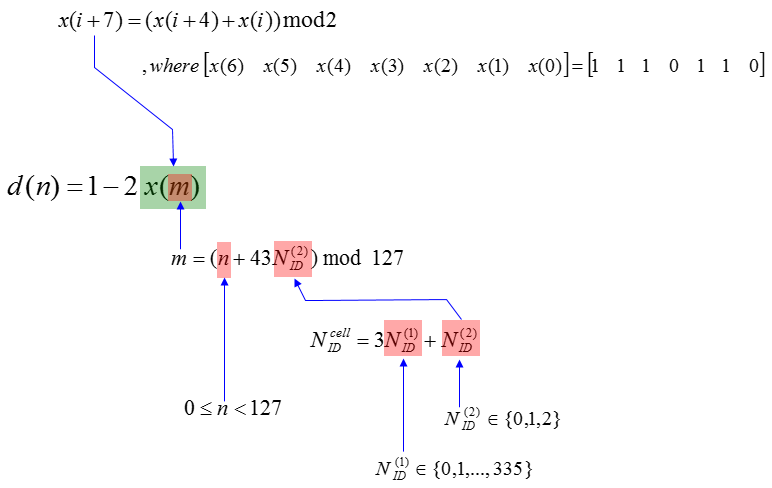

**（2）SSS Sequence Generation**

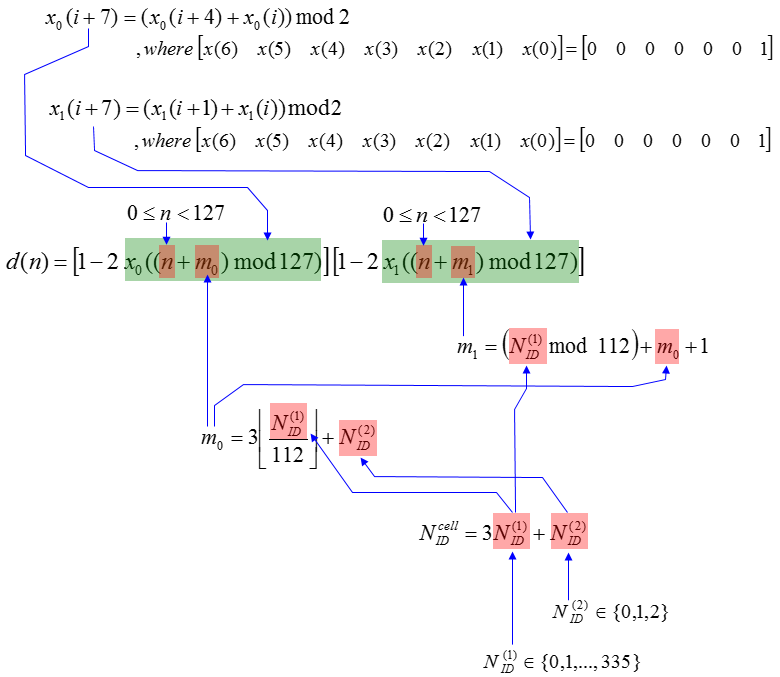

**（3）PBCH Payload Generation**

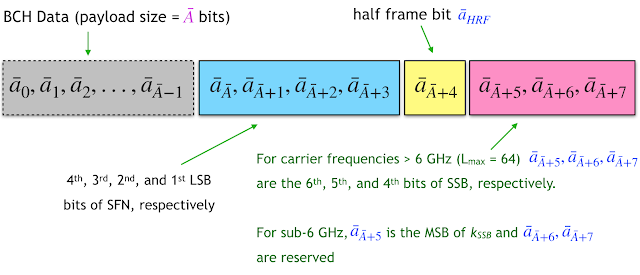

**（4）PBCH DMRS**

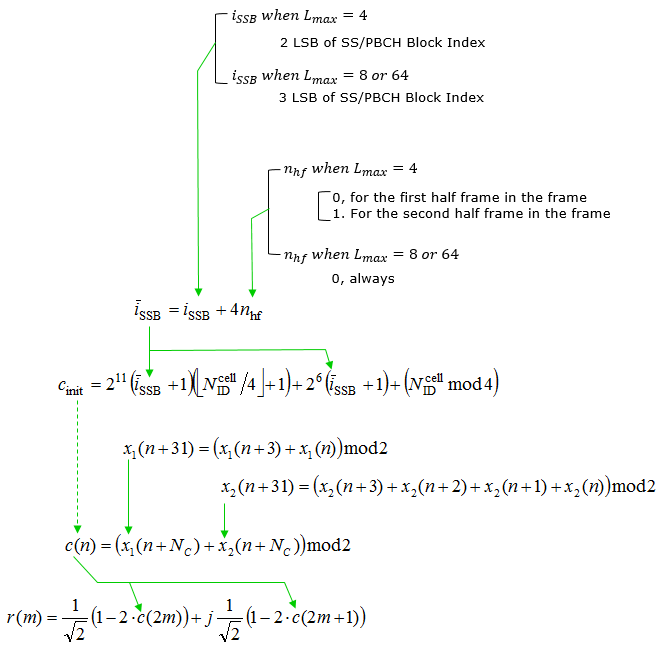

carrierGrid = nrResourceGrid(carrier);
grid = repmat(carrierGrid, 1, carrier.SlotsPerSubframe*5);

% For each transmitted SS/PBCH block
ncellid = carrier.NCellID;
pss_offset = 1;
sss_offset = 2;
pbchDmrs_offset = 3;
pbch_offset = 4;
for i = 1:numel(info.SSBIndex)

    % Timing-related parameters for this SS/PBCH block
    SSBIndex = info.SSBIndex(i);
    i_SSB = info.i_SSB(i);
    ibar_SSB = info.ibar_SSB(i);
    
    % Create SS/PBCH block resource grid
    ssbGrid = complex(zeros([240 4 1]));

    % PSS
    pss = nrPSS(ncellid);
    pssInd = nrPSSIndices();
    ssbGrid(pssInd) = pss.*pss_offset;

    % SSS
    sss = nrSSS(ncellid);
    sssInd = nrSSSIndices();
    ssbGrid(sssInd) = sss.*sss_offset;
    
    % PBCH DM-RS
    pbchDmrs = nrPBCHDMRS(ncellid,ibar_SSB);
    pbchDmrsInd = nrPBCHDMRSIndices(ncellid);
    ssbGrid(pbchDmrsInd) = pbchDmrs.*pbchDmrs_offset;
    
    % BCH
    if (info.L==64)
        idxoffset = SSBIndex;
    else
        idxoffset = info.k_SSB;
    end
    cw = nrBCH(mibpayload, fix(burst.NFrame),burst.NHalfFrame,info.L,idxoffset,ncellid);
    
    % PBCH
    v = i_SSB;
    pbch = nrPBCH(cw,ncellid,v);
    pbchInd = nrPBCHIndices(ncellid);
    ssbGrid(pbchInd) = pbch.*pbch_offset;

    % Map SSB grid to carrier grid
    occupiedSymbols = info.OccupiedSymbols(i,:);
    grid(info.OccupiedSubcarriers,occupiedSymbols,:) = ssbGrid;
end

**对资源网格画图显示**

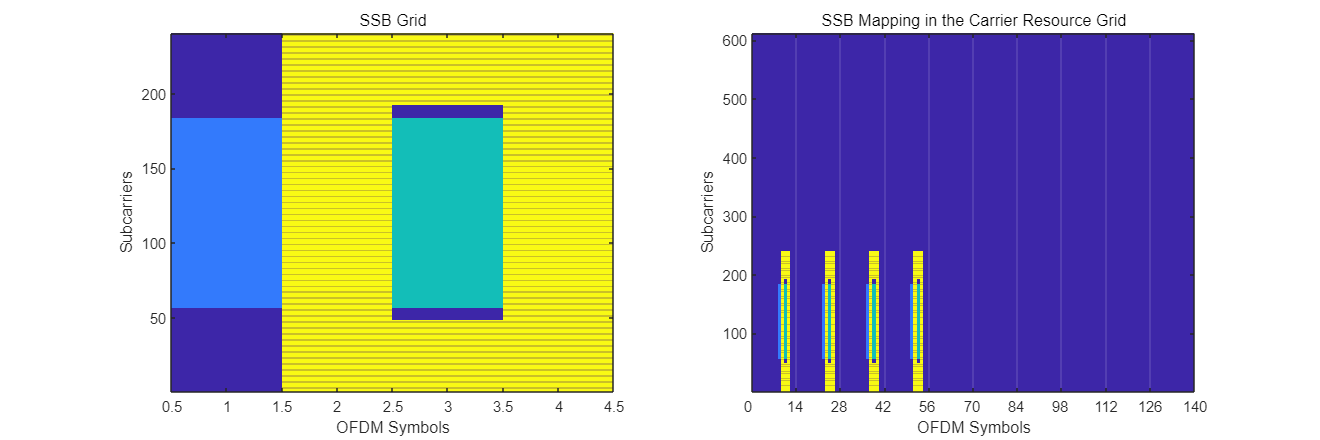

fig = figure;
fig.Position = [100 100 1200 400];

subplot(1,2,1);
imagesc(abs(ssbGrid));
set(gca, 'YDir', 'normal');
xlabel('OFDM Symbols');
ylabel('Subcarriers');
title('SSB Grid');

subplot(1,2,2);
imagesc(abs(grid));
set(gca, 'XLim', [0.5, carrier.SlotsPerSubframe*5*14+0.5]);
set(gca, 'XTick', (0:14:carrier.SlotsPerSubframe*5*14)+0.5);
set(gca, 'XTickLabel', (0:14:carrier.SlotsPerSubframe*5*14));
set(gca, 'XGrid', 'on');
set(gca, 'GridColor', 'white');
set(gca, 'YDir', 'normal');
xlabel('OFDM Symbols');
ylabel('Subcarriers');
title('SSB Mapping in the Carrier Resource Grid');

**相关函数**

根据SSB配置确定SSB的相关信息。

function ssbStartSymbols = ssBurstStartSymbols(burst)

    ssbBlockPattern = burst.BlockPattern;
    Lmax = length(burst.TransmittedBlocks);

    % 'alln' gives the overall set of SS block indices 'n' described in 
    % TS 38.213 Section 4.1, from which a subset is used for each Case A-E
    alln = [0; 1; 2; 3; 5; 6; 7; 8; 10; 11; 12; 13; 15; 16; 17; 18];
    
    cases = {'Case A' 'Case B' 'Case C' 'Case D' 'Case E'};
    m = [14 28 14 28 56];
    i = {[2 8] [4 8 16 20] [2 8] [4 8 16 20] [8 12 16 20 32 36 40 44]};
    nn = [2 1 2 16 8];
    
    caseIdx = find(strcmpi(ssbBlockPattern,cases));
    if (any(caseIdx==[1 2 3]))
        if (Lmax==4)
            nn = nn(caseIdx);
        elseif (Lmax==8)
            nn = nn(caseIdx) * 2;
        else
            error('For %s, the SSBTransmitted bitmap must be of length 4 or 8.',cases{caseIdx});
        end
    else
        if (Lmax==64)
            nn = nn(caseIdx);
        else
            error('For %s, the SSBTransmitted bitmap must be of length 64.',cases{caseIdx});
        end
    end
    
    n = alln(1:nn);
    ssbStartSymbols = (i{caseIdx} + m(caseIdx)*n).';
    ssbStartSymbols = ssbStartSymbols(:).';   
end

function info = ssBurstInfo(burst)

    info.L = length(burst.TransmittedBlocks);

    info.SSBIndex = find(burst.TransmittedBlocks) - 1;
    
    n_hf = mod(burst.NHalfFrame,2);
    if (info.L==4)
        info.i_SSB = mod(info.SSBIndex,4);
        info.ibar_SSB = mod(info.SSBIndex,4) + 4*n_hf;
    else
        info.i_SSB = mod(info.SSBIndex,8);
        info.ibar_SSB = mod(info.SSBIndex,8);
    end
    
    ssbStartSymbols = ssBurstStartSymbols(burst);
    valid_ssbStartSymbols = ssbStartSymbols(logical(burst.TransmittedBlocks));
    symbol_offset = repmat([1 2 3 4], length(valid_ssbStartSymbols), 1);
    valid_ssbSymbols = repmat(valid_ssbStartSymbols', 1, 4);
    info.OccupiedSymbols =  valid_ssbSymbols + symbol_offset;
    
    info.k_SSB = burst.k_SSB;
    info.OccupiedSubcarriers = burst.k0_offset + (1:240).';
end